# Sampling values taking with 0%, 5%, 10%, 20%, 30%, 40%, 50% delay in consideration in 2 activities respectively randomly

#### [5 cases have been taken]

Activity matrix containing 14 actitvities with Optimistic time, Most likely time & Pessimistic time respectively

Activity = [ 40,50,60; 40,60,80; 80,80,140; 100,110,180; 60,70,80; 120,120,120; 40,110,120; 50,60,70; 100,100,100; 70,80,150; 60,70,80; 60,80,100; 70,70,70; 20,50,80]

Activity =     40    50    60
    40    60    80
    80    80   140
   100   110   180
    60    70    80
   120   120   120
    40   110   120
    50    60    70
   100   100   100
    70    80   150


Sampled matrix where the final sampled values will be scored

Sampled = zeros(14,5,10000);

Code for sampling :

for i=1:5
    z_new = Activity;
    r = randperm(14,14)
    x = [0,0,5,5,10,10,20,20,30,30,40,40,50,50];
    for j=1:14
       s = r(1,j);
       z_new(s,3) = round(z_new(s,3) + (x(1,j)/100)*z_new(s,3),2);
    end
    disp(z_new)
    for k=1:14
      a = z_new(k,1);
      b = z_new(k,3);
      value = round((b-a).*rand(10000,1) + a,2);
      Sampled(k,i,:) = value;
    end    
end

r =     14    12     5     4     3    13     7     8     9     2    10     6    11     1


    40    50    90
    40    60   104
    80    80   154
   100   110   189
    60    70    84
   120   120   168
    40   110   144
    50    60    84
   100   100   130
    70    80   210
    60    70   120
    60    80   100
    70    70    77
    20    50    80



r =     10    13    11     5     3     7     2     6     4     8    14    12     9     1


    40    50    90
    40    60    96
    80    80   154
   100   110   234
    60    70    84
   120   120   144
    40   110   132
    50    60    91
   100   100   150
    70    80   150
    60    70    84
    60    80   140
    70    70    70
    20    50   112



r =      8     6    12     9     7     1    13    14     4    10    11     3     2     5


    40    50    66
    40    60   120
    80    80   196
   100   110   234
    60    70   120
   120   120   120
    40   110   132
    50    60    70
   100   100   105
    70    80   195
    60    70   112
    60    80   105
    70    70    84
    20    50    96



r =      4     7     6     5     1     3     2    11    13    12    10    14     9     8


    40    50    66
    40    60    96
    80    80   154
   100   110   180
    60    70    84
   120   120   126
    40   110   120
    50    60   105
   100   100   150
    70    80   210
    60    70    96
    60    80   130
    70    70    91
    20    50   112



r =      3    12     9     6     5    13     8     2    11     4     7    10    14     1


    40    50    90
    40    60    96
    80    80   140
   100   110   234
    60    70    88
   120   120   126
    40   110   168
    50    60    84
   100   100   105
    70    80   210
    60    70   104
    60    80   100
    70    70    77
    20    50   120



disp(Sampled)


(:,:,1) =

   66.2900   66.7400   46.5900   63.5300   40.5100
   46.3600   86.7400   73.8300   74.8900   75.2100
  151.3000   97.8500  136.1700  121.5700   96.4300
  157.2400  153.0900  155.0600  128.0100  180.2800
   77.6200   66.9100   82.7300   79.2000   86.5900
  132.9700  138.3100  120.0000  125.3800  121.0800
  107.9200  111.2200   52.6900  104.7800   92.5700
   66.2000   63.5700   59.1300   80.4900   67.0300
  114.8400  136.2900  104.3000  138.2700  101.8800
  109.6700   99.0200   86.1600  155.7100   82.8300
  100.8000   71.5600   81.6600   92.9800   70.5700
   72.7600  117.1800   92.0500   86.3400   82.2600
   75.8300   70.0000   77.7600   89.0000   73.2800
   57.8600   23.8700   80.2600   69.7800   68.2300


(:,:,2) =

   83.9300   74.5400   60.1400   42.6200   40.6600
   90.5600   55.7800   69.1500   56.4900   48.8800
   85.0600  120.0100  112.6700  105.1200  134.7600
  176.9400  133.1600  156.9900  159.9200  199.4600
   63.5700   78.4700  118.7500   64.4500   72.8800
  121.

max1 = max(Sampled(2,1,:))

max1 = 103.9900

min1 = min(Sampled(2,1,:))

min1 = 40

C1_ = Sampled(:,1,:);
C2_ = Sampled(:,2,:);
C3_ = Sampled(:,3,:);
C4_ = Sampled(:,4,:);
C5_ = Sampled(:,5,:);

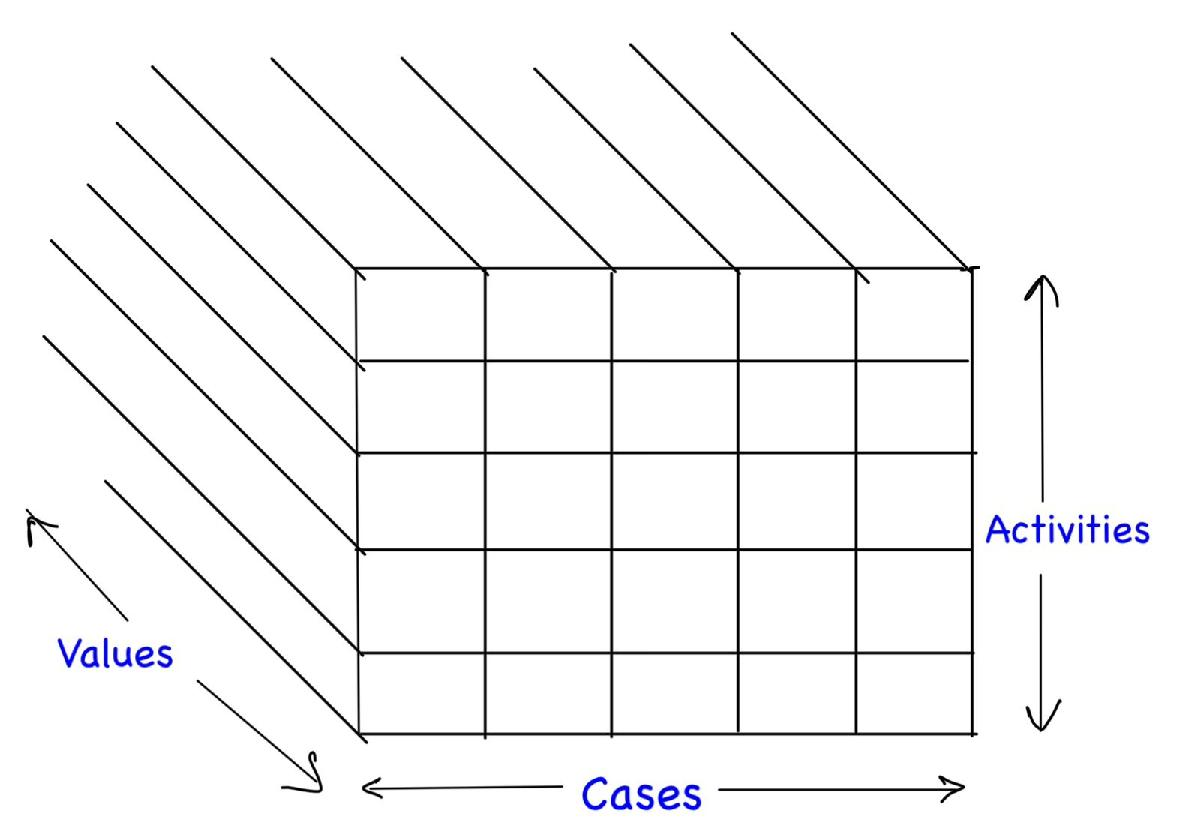Sampled Matrix